# **5. Interpolation (**`interp1, polyfit`** and **`polyval`**)**

clear;
clc;
figure();

**Scatter plot**

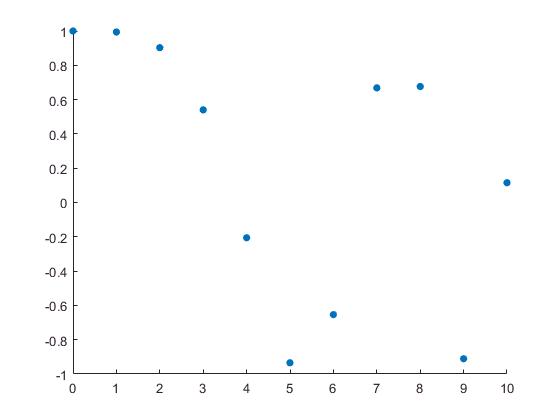

x=linspace(0,10,11);
y=cos(-x.^2/9);
scatter(x,y,30,'filled')

**Interpolation **

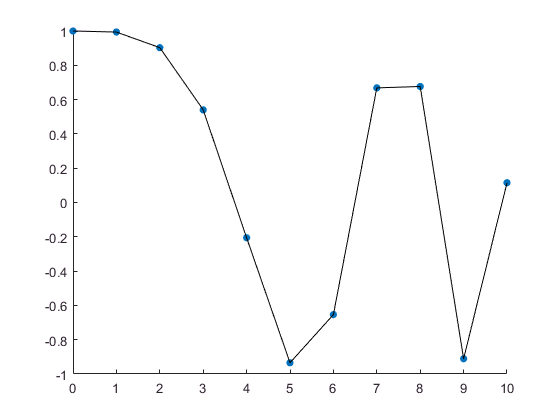

% (Default) linear interpolation
figure();
scatter(x,y,30,'filled');
hold on;
xq=linspace(0,10,101);
yq=interp1(x,y,xq);
plot(xq,yq,'k-')

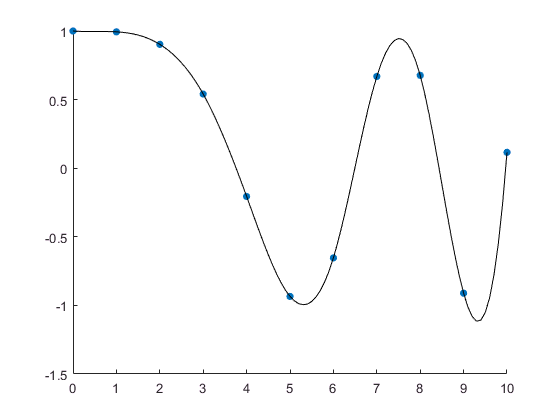

% 'spline': cubic spline with not-a-knot end condition
% x0, x1, ..., xN: third derivative is continuous at x1 and xN-1
figure();
scatter(x,y,30,'filled');
hold on;
xq=linspace(0,10,101);
yq=interp1(x,y,xq,'spline');
plot(xq,yq,'k-')

**Subplots**

ax=[-0.5,10.5,-1.2,1.2];
x0=1.2;

figure();
%subplots
subplot(3,3,1);
x=linspace(0,10,11);
y=cos(-x.^2/9);
scatter(x,y,20,'blue','filled')
axis(ax)
title('11 points')

%subplots
subplot(3,3,2);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,10,101);
yq=interp1(x,y,xq);
y0=interp1(x,y,x0);
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('linear')

% subplots
subplot(3,3,3);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,10,101);
yq=interp1(x,y,xq,'spline');
y0=interp1(x,y,x0,'spline');
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('cubic spline')

% subplots
subplot(3,3,4);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,10,101);
yq=polyval(polyfit(x,y,2),xq);
y0=polyval(polyfit(x,y,2),x0);
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('poly-2')

% subplots
subplot(3,3,5);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,10,101);
yq=polyval(polyfit(x,y,3),xq);
y0=polyval(polyfit(x,y,3),x0);
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('poly-3')

% subplots
subplot(3,3,6);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,10,101);
yq=polyval(polyfit(x,y,10),xq);

y0=polyval(polyfit(x,y,10),x0);

plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('poly-10')

% subplots
subplot(3,3,7);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,2,21);
yq=polyval(polyfit(x(1:3),y(1:3),2),xq);
y0=polyval(polyfit(x(1:3),y(1:3),2),x0);
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('poly-2-1')

% subplots
subplot(3,3,8);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(1,3,21);
yq=polyval(polyfit(x(2:4),y(2:4),2),xq);
y0=polyval(polyfit(x(2:4),y(2:4),2),x0);
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('poly-2-2')

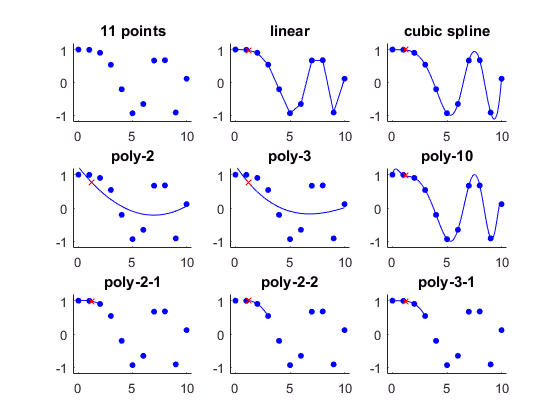

% subplots
subplot(3,3,9);
scatter(x,y,20,'blue','filled')
hold on;
xq=linspace(0,3,31);
yq=polyval(polyfit(x(1:4),y(1:4),3),xq);
y0=polyval(polyfit(x(1:4),y(1:4),3),x0);
plot(xq,yq,'b-')
plot(x0,y0,'rx')
axis(ax)
title('poly-3-1')

**Use loop.**

clear;

x = -1.1447

ans = 9

ans = 11

ans =     15    25

    15


    15


********************************************


Example 3:


********************************************


********************************************


Example 4:


********************************************


     S       K        r         q       sigma       T         c   
    ____    ____    ______    ______    _____    _______    ______
    1403    1350    0.0534    0.0118     0.26    0.10278    80.828
    1403    1375    0.0534    0.0118    0.267    0.10278    66.084
    1403    1400    0.0534    0.0118    0.231    0.10278    45.894
    1403    1425    0.0534    0.0118    0.213    0.10278    30.955
    1403    1450    0.0534    0.0118    0.198    0.10278    19.224


********************************************


Example 4:


********************************************



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x =     6.5041    0.9084


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<stopping criteria 

x =     1.4000    1.7000

clc;
figure();
x=linspace(0,10,11);
y=cos(-x.^2/9);
xp=linspace(0,10,101);
xp21=linspace(0,2,21);
xp22=linspace(1,3,21);
xp31=linspace(0,3,31);
xps={[], xp, xp; ...
     xp, xp, xp; ...
     xp21, xp22, xp31};
yps={[], ...
     interp1(x,y,xp), ...
     interp1(x,y,xp,'spline'); ...
     polyval(polyfit(x,y,2),xp), ...
     polyval(polyfit(x,y,3),xp), ...
     polyval(polyfit(x,y,10),xp); ...
     polyval(polyfit(x(1:3),y(1:3),2),xp21), ...
     polyval(polyfit(x(2:4),y(2:4),2),xp22), ...
     polyval(polyfit(x(1:4),y(1:4),3),xp31)};
x0=1.2;
xp0={[], x0, x0; x0, x0, x0; x0, x0, x0};
yp0={[], ...

     interp1(x,y,x0), ...
     interp1(x,y,x0,'spline'); ...
     polyval(polyfit(x,y,2),x0), ...
     polyval(polyfit(x,y,3),x0), ...
     polyval(polyfit(x,y,10),x0); ...
     polyval(polyfit(x(1:3),y(1:3),2),x0), ...
     polyval(polyfit(x(2:4),y(2:4),2),x0), ...
     polyval(polyfit(x(1:4),y(1:4),3),x0)};
titles={'11 points', 'linear', 'cubic spline';
        'poly-2', 'poly-3', 'poly-10';
        'poly-2-1', 'poly-2-2', 'poly-3-1'};


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the default value of the optimality tolerance,
and constraints are satisfied to within the default value of the constraint tolerance.

<

x =     0.6667
    1.3333

Expression or statement is incomplete or incorrect.

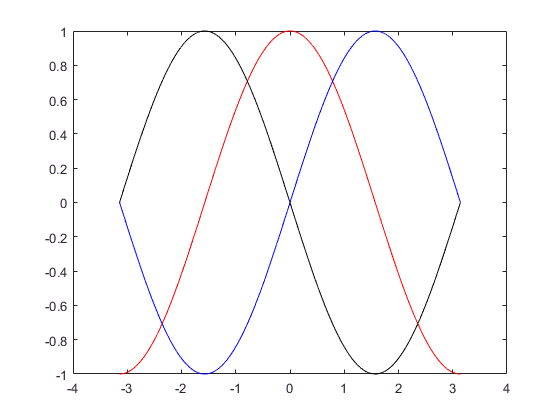

p = 21.3333

p = 1

p = 0.6667

for i=1:3
    for j=1:3
        k=j+(i-1)*3;
        subplot(3,3,k);
        scatter(x,y,20,'blue','filled');
        hold on;
        plot(xps{i,j},yps{i,j},'b-')
        plot(xp0{i,j},yp0{i,j},'rx')
        axis([-0.5,10.5,-1.2,1.2]);
        title(titles{i,j})
    end
end